clear;

profile = Profile.ski;
clockTimeLimit = 30; % 体験時間 (s)
period = 2; % 歩行周期 (s)

legForwardTimeRate = 2; % 足スライダ前進 時間比
legBackwardTimeRate = 1; % 足スライダ後退 時間比

stockForwardTimeRate = 2; % ストックスライダ前進 時間比
stockBackwardTimeRate = 1; % ストックスライダ後退 時間比

upTimeRate = 5; % 伸縮 持ち上げ 時間比
downTimeRate = 1; % 伸縮 降下 時間比

stockFlyingTimeRate = 2.2; % ストック空中時間比
stockGroundTimeRate = 0.8; % ストック接地時間比

tiltBackwardTimeRate = stockForwardTimeRate;
tiltForwardTimeRate = stockBackwardTimeRate;

liftLength = 15; % 椅子 リフト長 単位 (mm)
pedalLength = 60; % ペダル長 単位 (mm)
seatSlideLength = 290; % 椅子 スライド長 単位 (mm)
extendLength = 300; % 伸縮長 単位 (mm)
stockSlideLength = 600; % ストック スライド長 単位 (mm)
tiltBackwardDeg = 10; % ストック 後傾角度 (deg)
tiltForwardDeg = -40; % ストック 前傾角度 (deg)


椅子 リフト

L = liftLength; % スライド長 単位 (mm)
startClockTime = 0; % 開始時刻 (s)
if legForwardTimeRate < legBackwardTimeRate
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
else
    clockTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) + period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
    deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    deltaTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
end
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period/2:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period/2:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

lifter = table(clockTime, deltaTime, absolutePosition)

lifter = 59×3 table
    clockTime    deltaTime    absolutePosition
    _________    _________    ________________

     1.3333       0.33333            15       
     1.6667       0.33333             0       
     2.3333       0.33333            15       
     2.6667       0.33333             0       
     3.3333       0.33333            15       
     3.6667       0.33333             0       
     4.3333       0.33333            15       
     4.6667       0.33333             0       
     5.3333       0.33333            15       
     5.6667       0.33333             0       
     6.3333       0.33333            15       
     6.6667       0.33333             0       
     7.3333       0.33333            15       
     7.6667       0.33333             0       
     8.3333       0.33333            15       
     8.6667       0.33333             0       


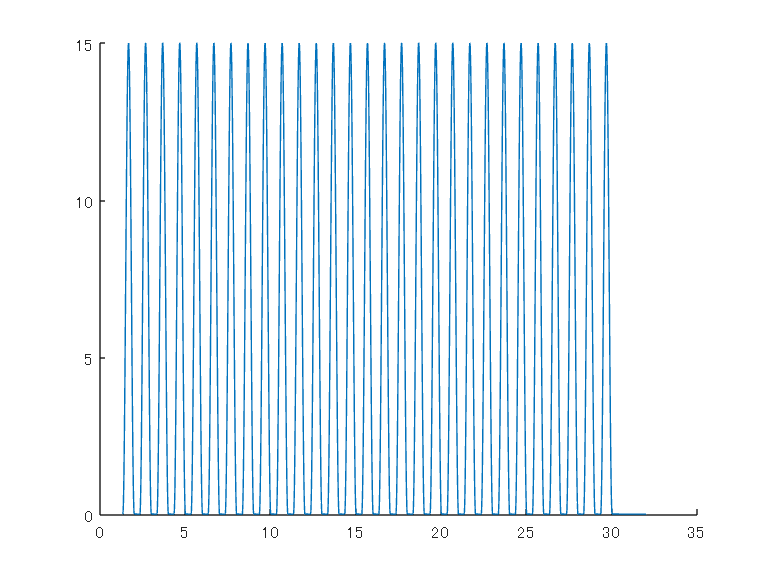

writetable(lifter, "lifter.csv");
figure;
[lifter_x, lifter_t] = showGraph(clockTime, deltaTime, absolutePosition);


% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)


左ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

leftPedal = table(clockTime, deltaTime, absolutePosition)

leftPedal = 31×3 table
    clockTime    deltaTime    absolutePosition
    _________    _________    ________________

     1.3333       0.66667            60       
          2        1.3333             0       
     3.3333       0.66667            60       
          4        1.3333             0       
     5.3333       0.66667            60       
          6        1.3333             0       
     7.3333       0.66667            60       
          8        1.3333             0       
     9.3333       0.66667            60       
         10        1.3333             0       
     11.333       0.66667            60       
         12        1.3333             0       
     13.333       0.66667            60       
         14        1.3333             0       
     15.333       0.66667            60       
         16        1.3333             0       


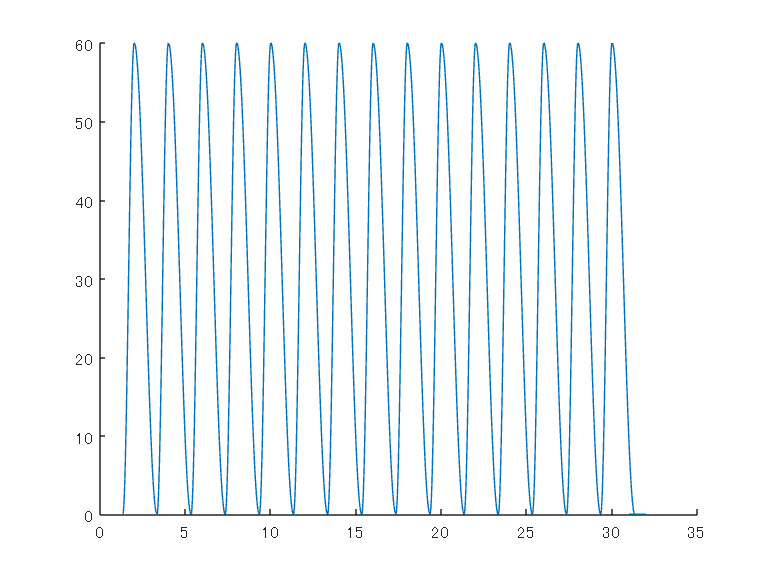

writetable(leftPedal, "leftPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[leftPedal_x, leftPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = period/2 + period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

rightPedal = table(clockTime, deltaTime, absolutePosition)

rightPedal = 29×3 table
    clockTime    deltaTime    absolutePosition
    _________    _________    ________________

     2.3333       0.66667            60       
          3        1.3333             0       
     4.3333       0.66667            60       
          5        1.3333             0       
     6.3333       0.66667            60       
          7        1.3333             0       
     8.3333       0.66667            60       
          9        1.3333             0       
     10.333       0.66667            60       
         11        1.3333             0       
     12.333       0.66667            60       
         13        1.3333             0       
     14.333       0.66667            60       
         15        1.3333             0       
     16.333       0.66667            60       
         17        1.3333             0       


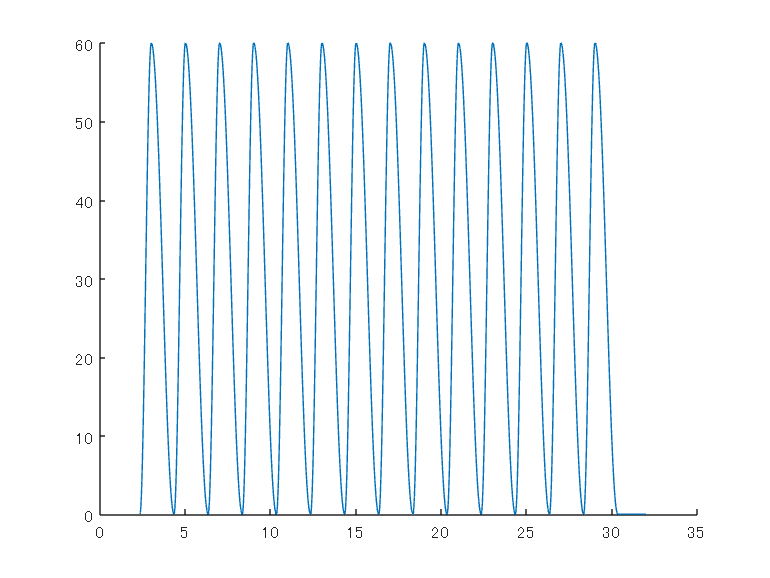

writetable(rightPedal, "rightPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[rightPedal_x, rightPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　左　スライダ

L = seatSlideLength; % スライド長 単位 (mm)
startClockTime = 0; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = L/2; % 単位 (mm)
positionB = -L/2; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

seatLeftSlider = table(clockTime, deltaTime, absolutePosition)

seatLeftSlider = 31×3 table
    clockTime    deltaTime    absolutePosition
    _________    _________    ________________

          0        1.3333            145      
     1.3333       0.66667           -145      
          2        1.3333            145      
     3.3333       0.66667           -145      
          4        1.3333            145      
     5.3333       0.66667           -145      
          6        1.3333            145      
     7.3333       0.66667           -145      
          8        1.3333            145      
     9.3333       0.66667           -145      
         10        1.3333            145      
     11.333       0.66667           -145      
         12        1.3333            145      
     13.333       0.66667           -145      
         14        1.3333            145      
     15.333       0.66667           -145      


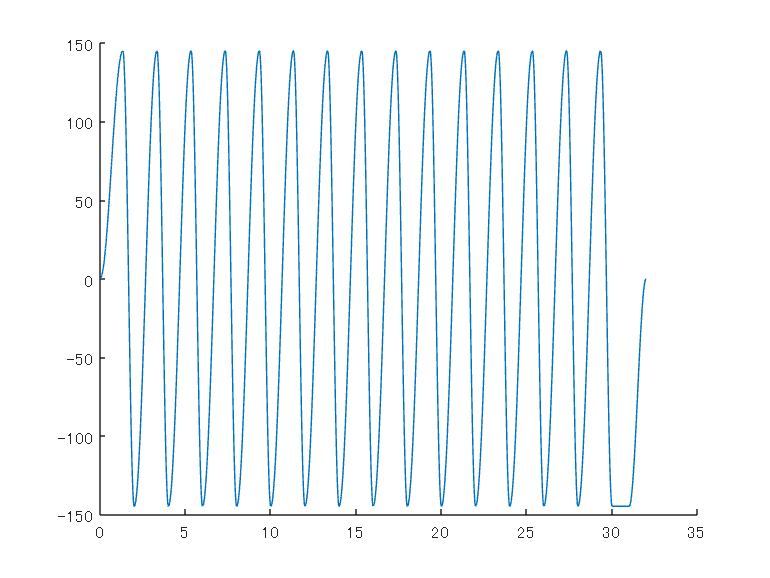

writetable(seatLeftSlider, "seatLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatLeftSlider_x, seatLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　右　スライダ

L = seatSlideLength; % スライド長 単位 (mm)
startClockTime = period/2; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = L/2; % 単位 (mm)
positionB = -L/2; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

seatRightSlider = table(clockTime, deltaTime, absolutePosition)

seatRightSlider = 29×3 table
    clockTime    deltaTime    absolutePosition
    _________    _________    ________________

          1        1.3333            145      
     2.3333       0.66667           -145      
          3        1.3333            145      
     4.3333       0.66667           -145      
          5        1.3333            145      
     6.3333       0.66667           -145      
          7        1.3333            145      
     8.3333       0.66667           -145      
          9        1.3333            145      
     10.333       0.66667           -145      
         11        1.3333            145      
     12.333       0.66667           -145      
         13        1.3333            145      
     14.333       0.66667           -145      
         15        1.3333            145      
     16.333       0.66667           -145      


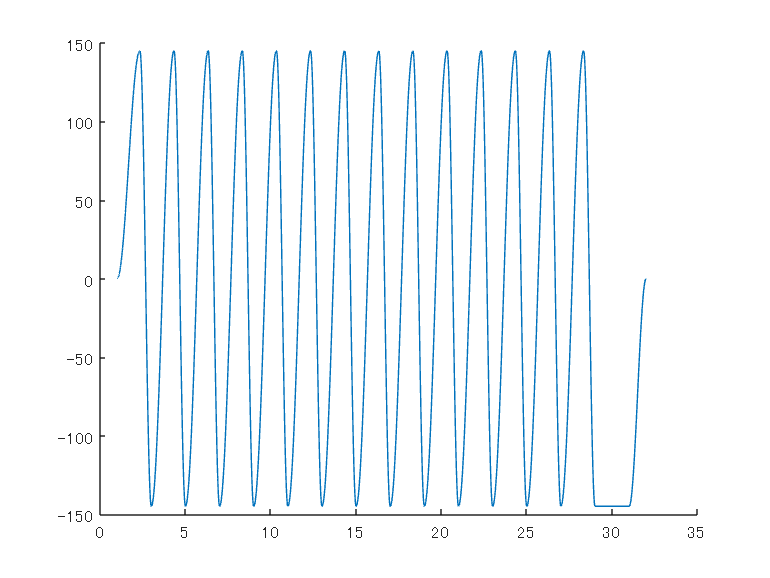

writetable(seatRightSlider, "seatRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatRightSlider_x, seatRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

if profile == Profile.walk

左ストックの伸縮　登山

    L = extendLength; % スライド長 単位 (mm)
    startClockTime = period/2; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeU = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;

    stockLeftExtend = table(clockTime, deltaTime, absolutePosition)
    writetable(stockLeftExtend, "stockLeftExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮　登山


    L = extendLength; % スライド長 単位 (mm)
    startClockTime = 0; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeU = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);

    stockRightExtend = table(clockTime, deltaTime, absolutePosition)
    writetable(stockRightExtend, "stockRightExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);
end

if profile == Profile.ski

左ストックの伸縮 クロスカントリー


    L = extendLength; % スライド長 単位 (mm)
    startClockTime = period/2; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate); % 単位 (s)
    deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate); % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 2*L/3; % 単位 (mm)
    positionSlowD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
    tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
    tmp = [positionUList; positionDList; positionSlowDList];
    absolutePosition = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;

    stockLeftExtend = table(clockTime, deltaTime, absolutePosition)
    writetable(stockLeftExtend, "stockLeftExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮　クロスカントリー

stockLeftExtend = 43×3 table
    clockTime    deltaTime    absolutePosition
    _________    _________    ________________

          1        1.2222           300       
     2.2222       0.24444           200       
     2.4667       0.53333             0       
          3        1.2222           300       
     4.2222       0.24444           200       
     4.4667       0.53333             0       
          5        1.2222           300       
     6.2222       0.24444           200       
     6.4667       0.53333             0       
          7        1.2222           300       
     8.2222       0.24444           200       
     8.4667       0.53333             0       
          9        1.2222           300       
     10.222       0.24444           200       
     10.467       0.53333             0       
         11        1.2222           300       


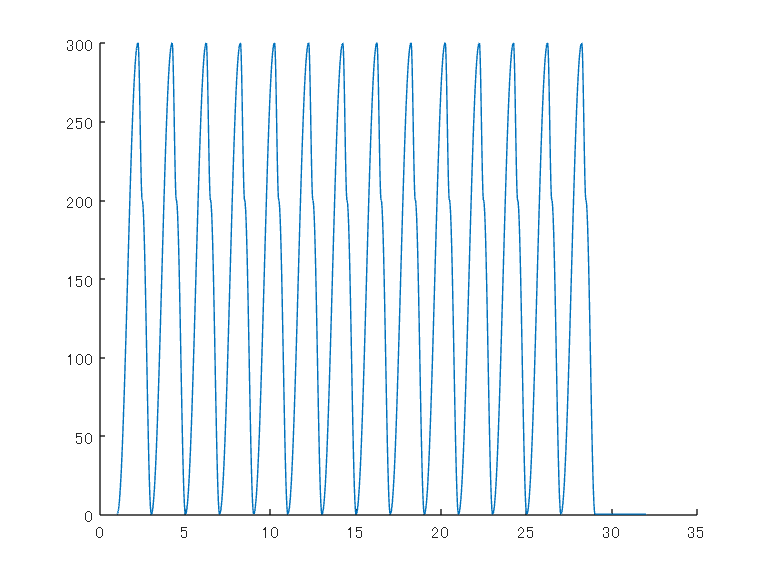

stockRightExtend = 46×3 table
    clockTime    deltaTime    absolutePosition
    _________    _________    ________________

          0        1.2222           300       
     1.2222       0.24444           200       
     1.4667       0.53333             0       
          2        1.2222           300       
     3.2222       0.24444           200       
     3.4667       0.53333             0       
          4        1.2222           300       
     5.2222       0.24444           200       
     5.4667       0.53333             0       
          6        1.2222           300       
     7.2222       0.24444           200       
     7.4667       0.53333             0       
          8        1.2222           300       
     9.2222       0.24444           200       
     9.4667       0.53333             0       
         10        1.2222           300       


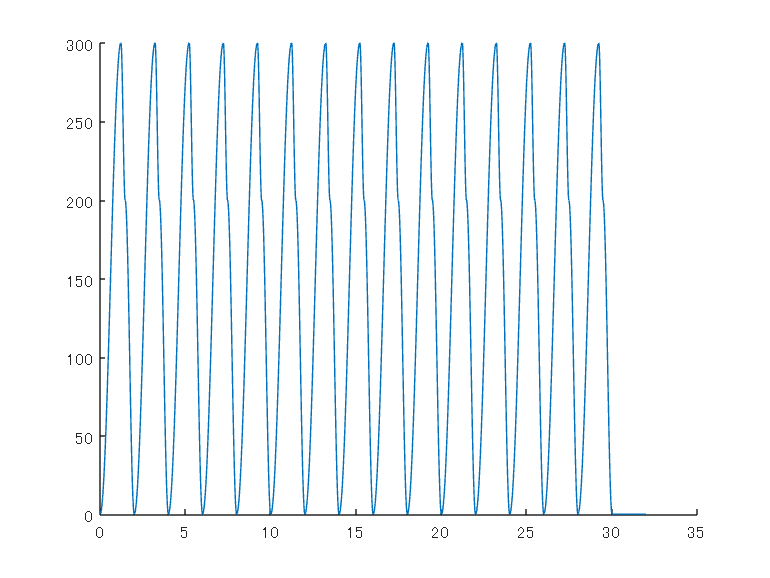


    L = extendLength; % スライド長 単位 (mm)
    startClockTime = 0; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate); % 単位 (s)
    deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate); % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 2*L/3; % 単位 (mm)
    positionSlowD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
    tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
    tmp = [positionUList; positionDList; positionSlowDList];
    absolutePosition = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;

    stockRightExtend = table(clockTime, deltaTime, absolutePosition)
    writetable(stockRightExtend, "stockRightExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);
end

左ストックのスライダ


L = stockSlideLength; % スライド長 単位 (mm)
startClockTime = period/2; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = L/2; % 単位 (mm)
positionB = -L/2; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

stockLeftSlider = table(clockTime, deltaTime, absolutePosition)

stockLeftSlider = 29×3 table
    clockTime    deltaTime    absolutePosition
    _________    _________    ________________

          1        1.3333            300      
     2.3333       0.66667           -300      
          3        1.3333            300      
     4.3333       0.66667           -300      
          5        1.3333            300      
     6.3333       0.66667           -300      
          7        1.3333            300      
     8.3333       0.66667           -300      
          9        1.3333            300      
     10.333       0.66667           -300      
         11        1.3333            300      
     12.333       0.66667           -300      
         13        1.3333            300      
     14.333       0.66667           -300      
         15        1.3333            300      
     16.333       0.66667           -300      


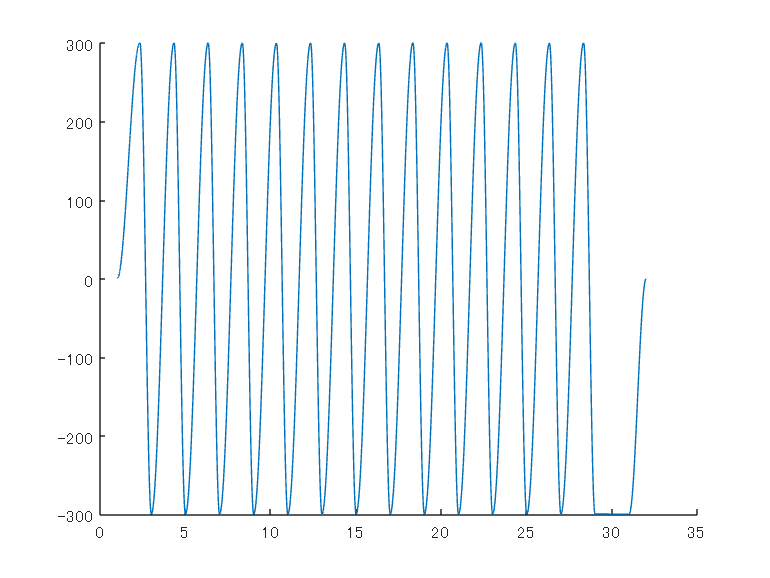

writetable(stockLeftSlider, "stockLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockLeftSlider_x, stockLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックのスライダ


L = stockSlideLength; % スライド長 単位 (mm)
startClockTime = 0; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = L/2; % 単位 (mm)
positionB = -L/2; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

stockRightSlider = table(clockTime, deltaTime, absolutePosition)

stockRightSlider = 31×3 table
    clockTime    deltaTime    absolutePosition
    _________    _________    ________________

          0        1.3333            300      
     1.3333       0.66667           -300      
          2        1.3333            300      
     3.3333       0.66667           -300      
          4        1.3333            300      
     5.3333       0.66667           -300      
          6        1.3333            300      
     7.3333       0.66667           -300      
          8        1.3333            300      
     9.3333       0.66667           -300      
         10        1.3333            300      
     11.333       0.66667           -300      
         12        1.3333            300      
     13.333       0.66667           -300      
         14        1.3333            300      
     15.333       0.66667           -300      


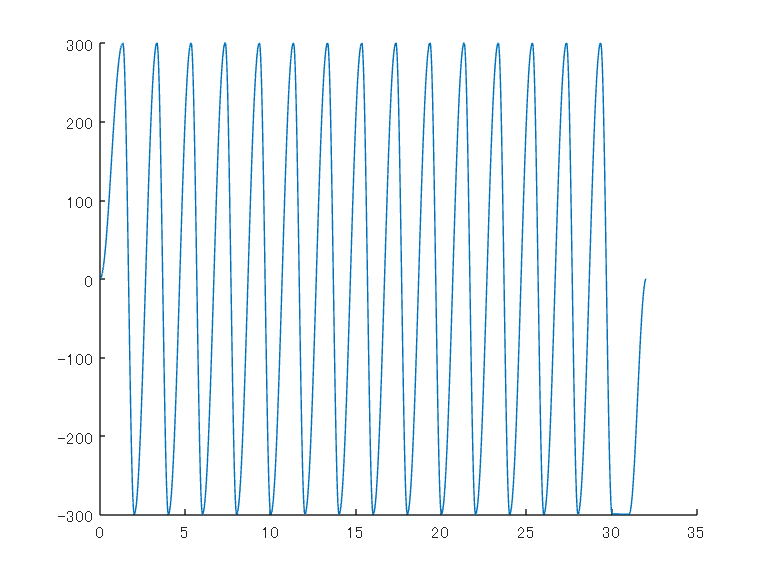

writetable(stockRightSlider, "stockRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightSlider_x, stockRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTime = period/2; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

leftTilt = table(clockTime, deltaTime, absolutePosition)

leftTilt = 29×3 table
    clockTime    deltaTime    absolutePosition
    _________    _________    ________________

          1        1.3333            10       
     2.3333       0.66667           -40       
          3        1.3333            10       
     4.3333       0.66667           -40       
          5        1.3333            10       
     6.3333       0.66667           -40       
          7        1.3333            10       
     8.3333       0.66667           -40       
          9        1.3333            10       
     10.333       0.66667           -40       
         11        1.3333            10       
     12.333       0.66667           -40       
         13        1.3333            10       
     14.333       0.66667           -40       
         15        1.3333            10       
     16.333       0.66667           -40       


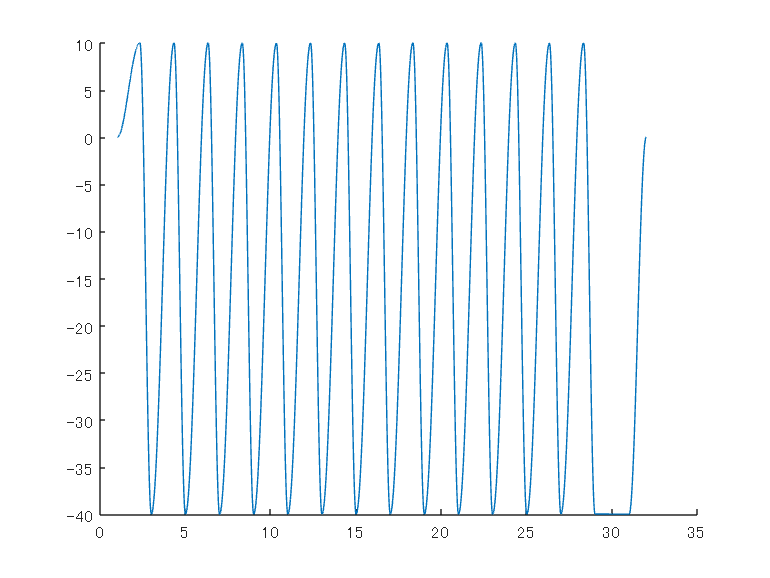

writetable(leftTilt, "leftTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[leftTilt_x, leftTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTime = 0; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

rightTilt = table(clockTime, deltaTime, absolutePosition)

rightTilt = 31×3 table
    clockTime    deltaTime    absolutePosition
    _________    _________    ________________

          0        1.3333            10       
     1.3333       0.66667           -40       
          2        1.3333            10       
     3.3333       0.66667           -40       
          4        1.3333            10       
     5.3333       0.66667           -40       
          6        1.3333            10       
     7.3333       0.66667           -40       
          8        1.3333            10       
     9.3333       0.66667           -40       
         10        1.3333            10       
     11.333       0.66667           -40       
         12        1.3333            10       
     13.333       0.66667           -40       
         14        1.3333            10       
     15.333       0.66667           -40       


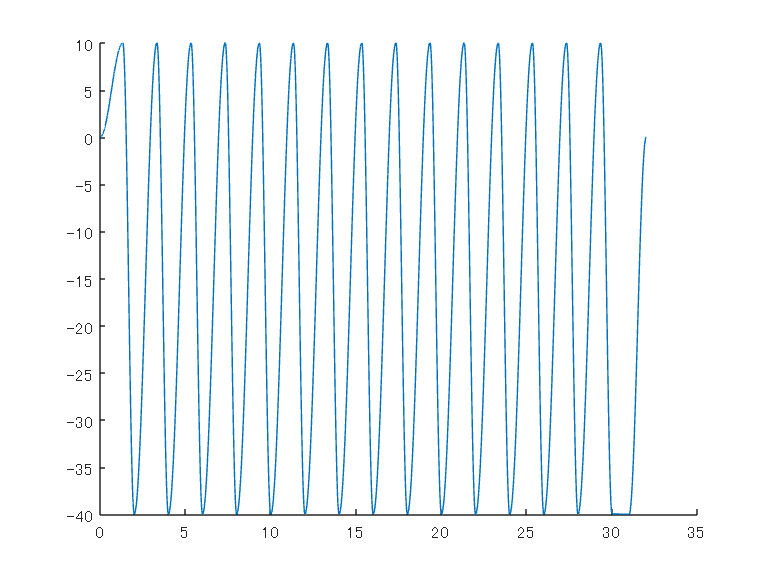

writetable(rightTilt, "rightTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[rightTilt_x, rightTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);


signal_lifter = timeseries(lifter_x, lifter_t, Name='lifter');
signal_leftPedal = timeseries(leftPedal_x, leftPedal_t, Name='leftPedal');
signal_rightPedal = timeseries(rightPedal_x, rightPedal_t, Name='rightPedal');
signal_seatLeftSlider = timeseries(seatLeftSlider_x, seatLeftSlider_t, Name='seatLeftSlider');
signal_seatRightSlider = timeseries(seatRightSlider_x, seatRightSlider_t, Name='seatRightSlider');
signal_stockLeftSlider = timeseries(stockLeftSlider_x, stockLeftSlider_t, Name='stockLeftSlider');
signal_stockRightSlider = timeseries(stockRightSlider_x, stockRightSlider_t, Name='stockRightSlider');
signal_stockLeftExtend = timeseries(stockLeftExtend_x, stockLeftExtend_t, Name='stockLeftExtend');
signal_stockRightExtend = timeseries(stockRightExtend_x, stockRightExtend_t, Name='stockRightExtend');
signal_leftTilt = timeseries(leftTilt_x, leftTilt_t, Name="leftTilt");
signal_rightTilt = timeseries(rightTilt_x, rightTilt_t, Name="rightTilt");

Scenario = Simulink.SimulationData.Dataset;

Scenario{1} = signal_lifter;
Scenario{2} = signal_leftPedal;
Scenario{3} = signal_rightPedal;
Scenario{4} = signal_seatLeftSlider;
Scenario{5} = signal_seatRightSlider;
Scenario{6} = signal_stockLeftExtend;
Scenario{7} = signal_stockRightExtend;
Scenario{8} = signal_stockLeftSlider;
Scenario{9} = signal_stockRightSlider;
Scenario{10} = signal_leftTilt;
Scenario{11} = signal_rightTilt;


% Scenario{2} = SignalStickRightPitch;
% Scenario{2}.Name = 'SignalStickRightPitch';
% Scenario{5} = signal_stockLeftPitch;
% Scenario{5}.Name = 'SignalStickLeftPitch';

save('scenario.mat', 'Scenario');

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end